#### With and Without LQR

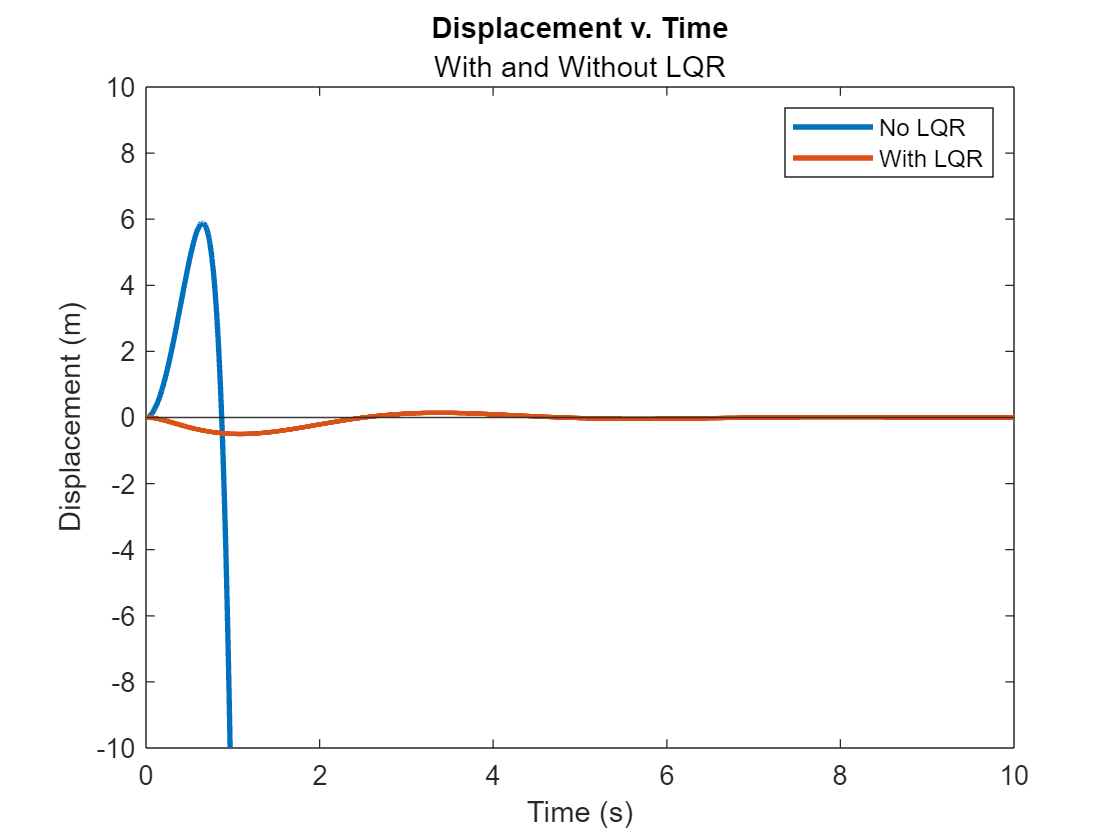

time_t = [0:0.001:20];
IP = InvertedPendulum("b",0.5);
V0 = [0;0; 0.175;0]; % initial bar tilt 10 degrees
%V0 = [0;0; 0;0];

Q = [1 0 0 0;
     0 0 0 0;
     0 0 1 0;
     0 0 0 0];
R=1;
N = [1;0;0;0];
Force =30;
sr = IP.euler_method(V0, Force, time=time_t, lqr=false, ...
    Q=Q,N=N,R=R, description='No LQR');

sr.plotX;

sr2 = IP.euler_method(V0, Force, time=time_t, lqr=true, ...
    Q=Q,N=N,R=R, description='With LQR');
hold on
sr2.plotX
hold off
xlim([0 10])
ylim([-10 10])
legend()
subtitle('With and Without LQR')

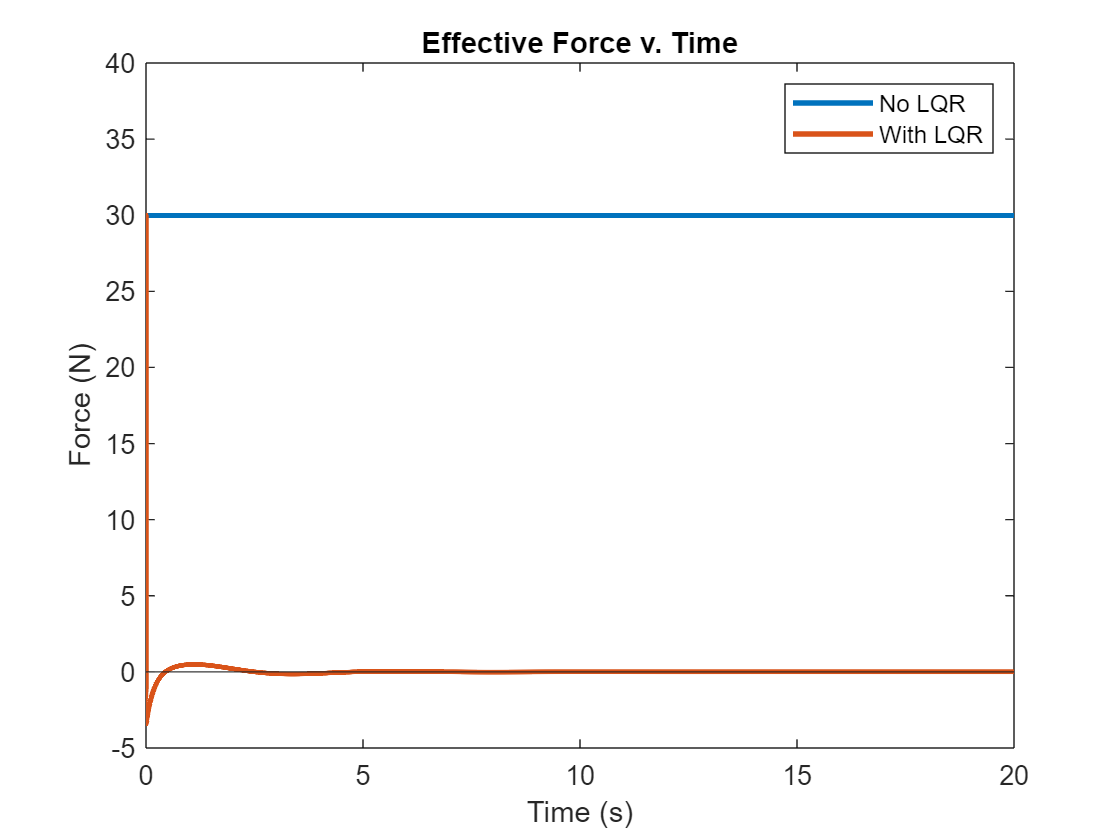

sr.plotF;
hold on
sr2.plotF
hold off
legend()
%xlim([0,0.25])
ylim([-5 40])

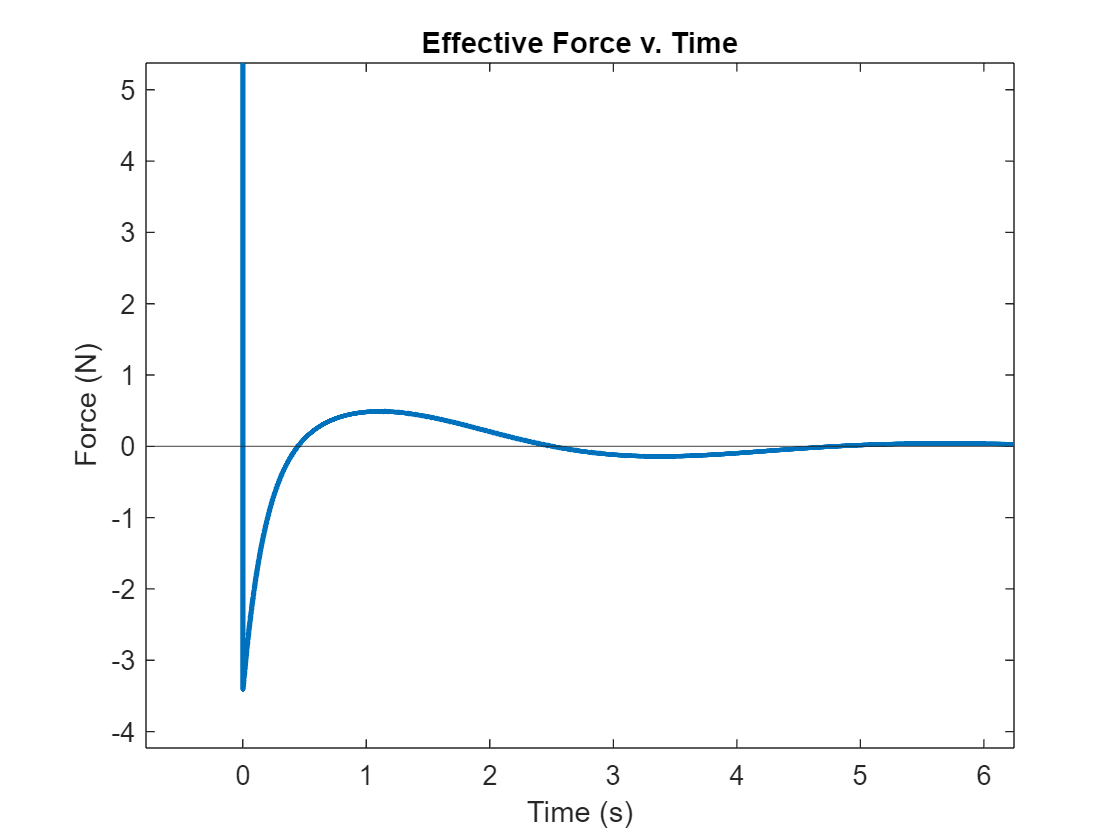

sr2.plotF

xlim([-0.78 6.24])
ylim([-4.23 5.38])

#### Varying Force

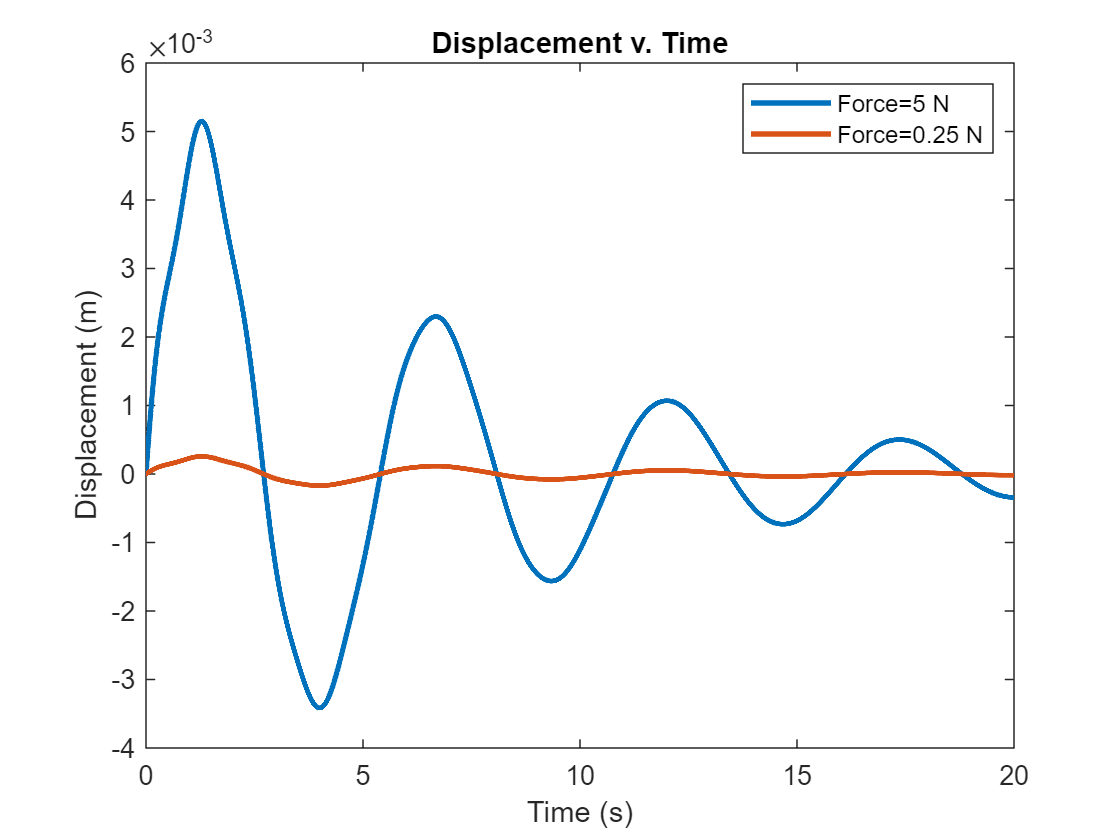

time_t = [0:0.001:20];
IP = InvertedPendulum();
%V0 = [0;0; 0.175;0]; % initial bar tilt 10 degrees
V0 = [0;0; 0;0];
Force =5;
Q = [1 0 0 0;
     0 0 0 0;
     0 0 1 0;
     0 0 0 0];
R=1;
N = [1;0;0;0];

sr = IP.euler_method(V0, 5, time=time_t, lqr=true, ...
    Q=Q,N=N,R=R, description='Force=5 N');

sr.plotX;

sr2 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q,N=N,R=R, description='Force=0.25 N');
hold on
sr2.plotX
hold off
legend()

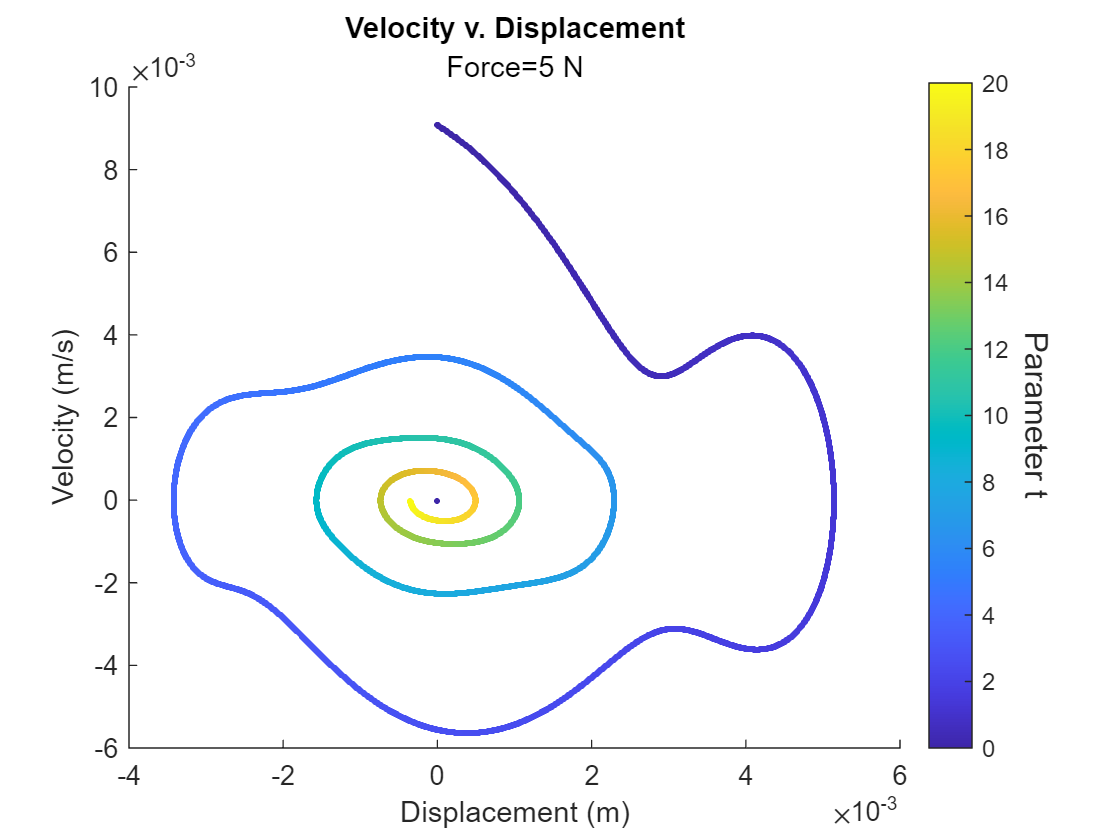

sr.plotXdX()

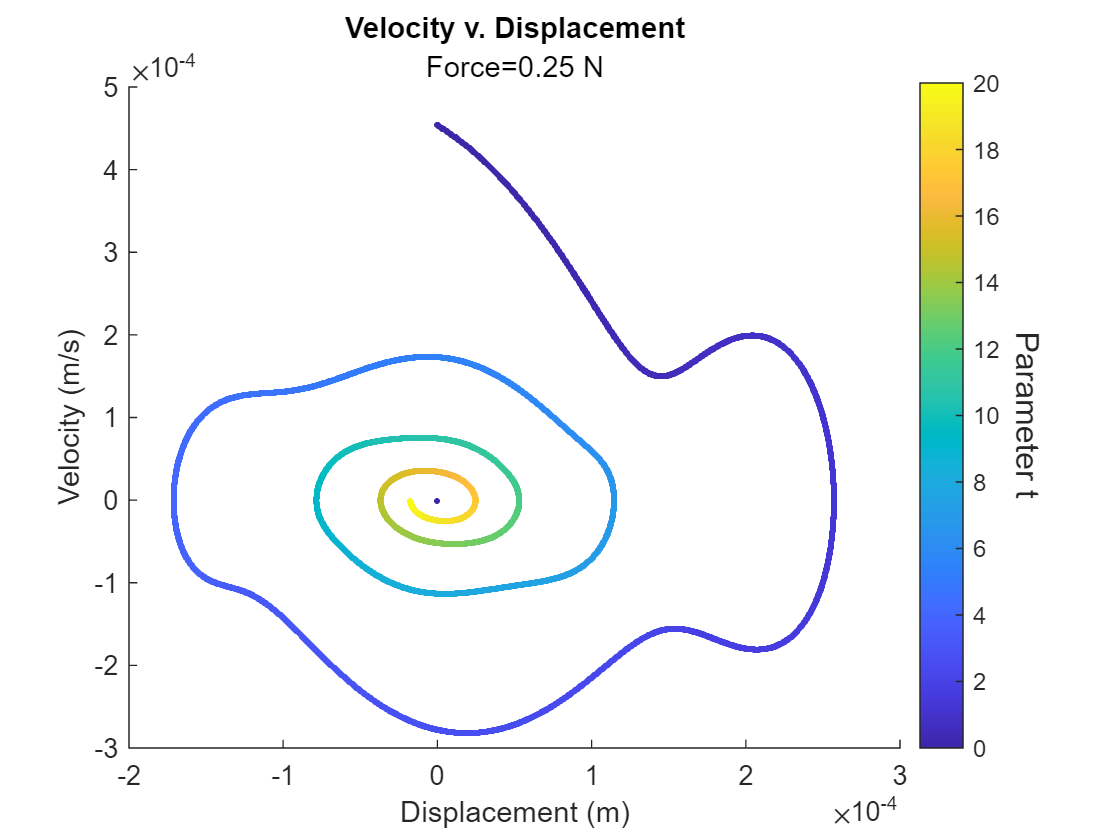

sr2.plotXdX()

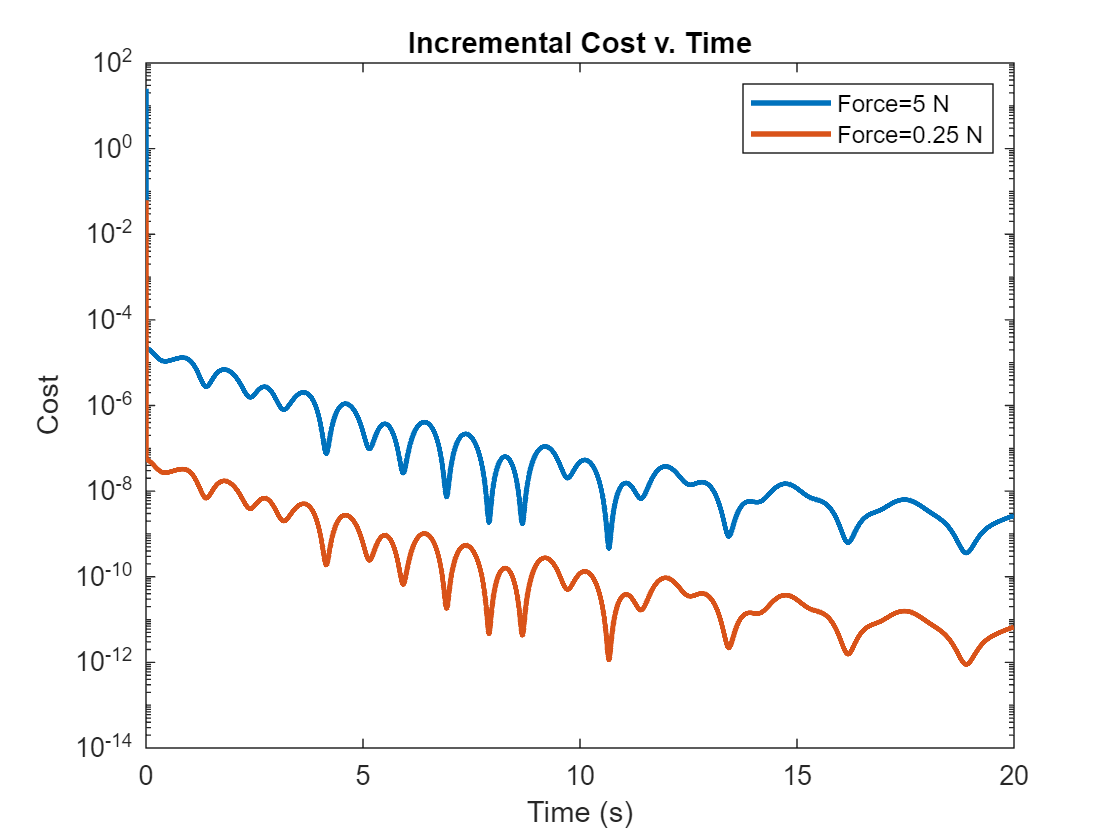

sr.plotdC;
hold on
sr2.plotdC
hold off
legend()

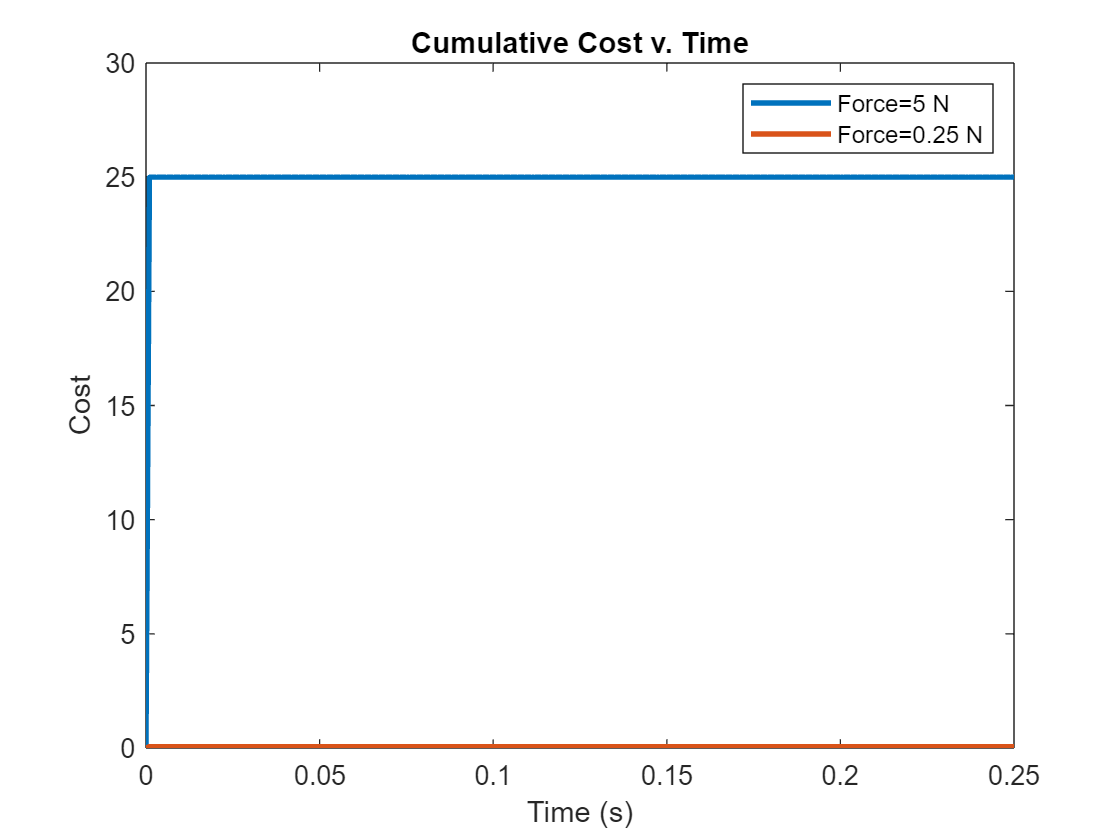


sr.plotdC(cumulative=true);
hold on
sr2.plotdC(cumulative=true)
hold off
legend()
xlim([0,0.25])

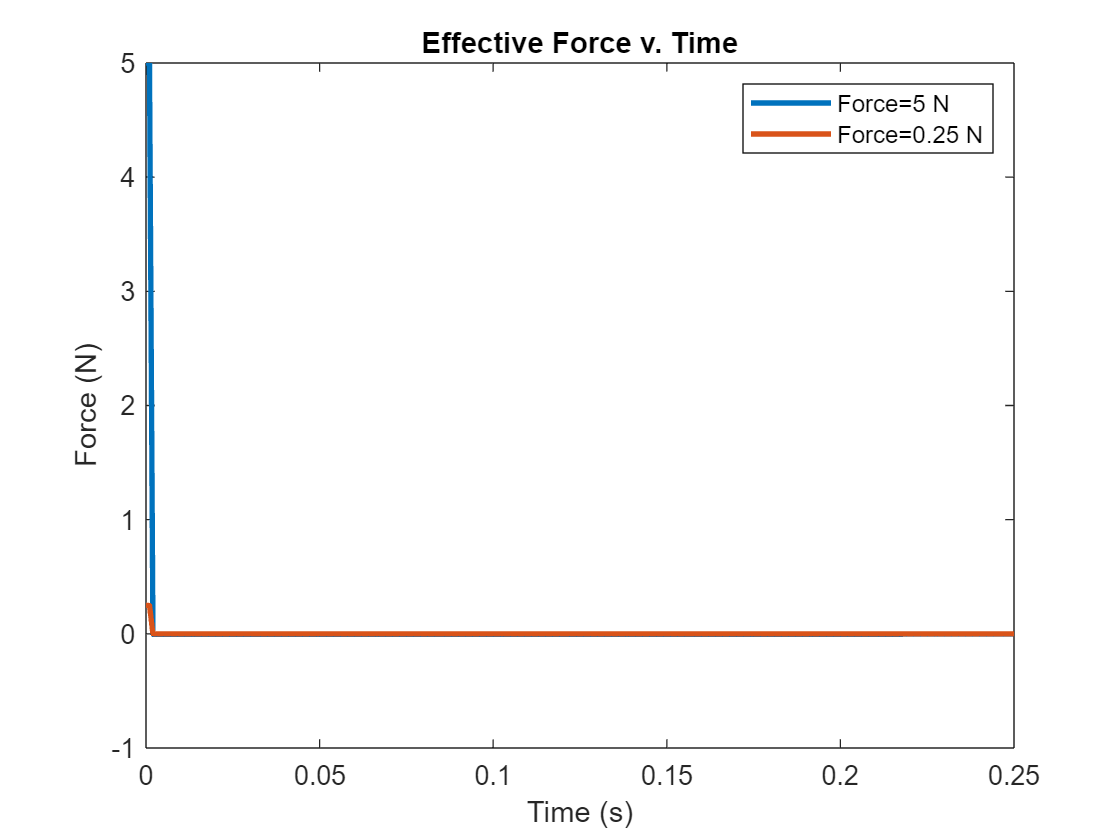

sr.plotF;
hold on
sr2.plotF
hold off
legend()
xlim([0,0.25])